# Immune scDRSA

**Author**: Scott Campit

## Summary

This script computes differentially sensitive reactions resulting from reaction knockouts in the metabolic reconstruction.

clear all;

### Load iHUMAN metabolic reconstruction

This code loads the iHUMAN metabolic reconstruction

% LOAD iHUMAN Results
load D:\Analysis\Immune\iHUMAN_PSA.mat;

Let's compute a Day 0 metabolic flux distribution.

eps = [];
kap = [];
rho = [];
isgenes = true;
eps2 = [];
pfba = true;

upgenes = [];
downgenes = [];

cntr = constrain_flux_regulation(model, ...
        upgenes, downgenes, ...
        kap, rho, ...
        eps, ...
        isgenes, ...
        pfba);

Get a new string ID to partition by day

tmp_id = split(neutrophil_id, " ");
tmp_id = string(floor(double(tmp_id(:, 3))));

idx0 = tmp_id == "0";
idx7 = tmp_id == "7";
idx14 = tmp_id == "14";
idx21 = tmp_id == "21";

## Relative flux analysis

This code block analyzes the relative change between time points from the knockout results. 

load D:\Analysis\Immune\neutrophil_scFBA.mat

Now let's get flux distributions corresponding to different days.

flux0 = tmpflx(idx0, :);
flux7 = tmpflx(idx7, :);
flux14 = tmpflx(idx14, :);
flux21 = tmpflx(idx21, :);

Now get fold change across different time points

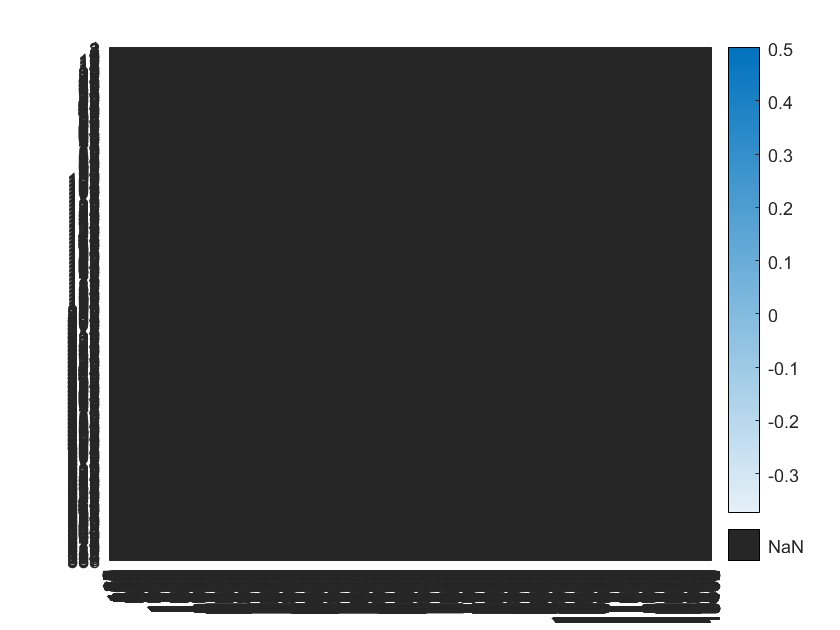

fc0007 = (abs(flux7)+1) ./ mean(abs(flux0)+1);
fc0714 = (abs(flux14)+1) ./ mean(abs(flux7)+1);
fc1421 = (abs(flux21)+1) ./ mean(abs(flux14)+1);

Concatenate vertically

df = [fc0007; fc0714; fc1421];

Get reaction IDs

ids = [model.rxns, model.rxnNames, model.subSystems];

Remove reactions that have no fold change

keep_idx = all(df-1, 1);
df = df(:, keep_idx);
ids = ids(keep_idx, :);

df = df - 1;

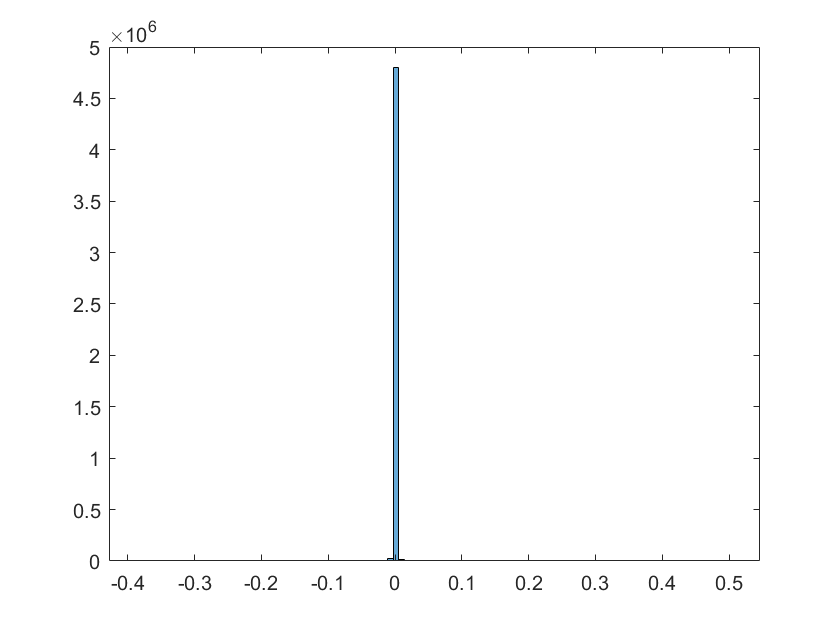

histogram(df, 100)

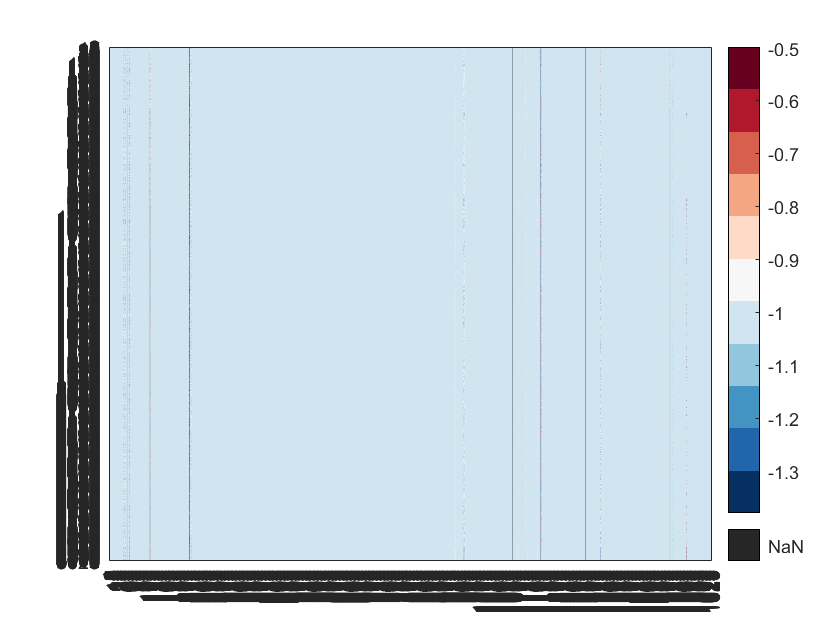

heatmap(df-1, ...
    'Colormap', redbluecmap, ...
    'GridVisible', 'off');

Create an average matrix for each time point and visualize that

df07 = df(1:sum(idx7), :);
df14 = df((sum(idx7)+1):(sum(idx14)+sum(idx7)), :);
df21 = df((sum(idx14)+sum(idx7)+1):sum(idx14)+sum(idx7)+sum(idx21), :);

Mean of metabolic fluxes

avg_df07 = mean(df07, 1);
avg_df14 = mean(df14, 1);
avg_df21 = mean(df21, 1);
avg_df = [avg_df07; avg_df14; avg_df21];

Variance of metabolic fluxes

var_df07 = var(df07, 1);
var_df14 = var(df14, 1);
var_df21 = var(df21, 1);
var_df = [var_df07; var_df14; var_df21];

Median of metabolic fluxes

med_df07 = median(df07, 1);
med_df14 = median(df14, 1);
med_df21 = median(df21, 1);
med_df = [med_df07; med_df14; med_df21];
med_overall = sum(med_df, 1);
med_df = [med_df; med_overall];

Median absolute deviation of metabolic fluxes

% Compute MAD
mad_df07 = mad(df07, 1);
mad_df14 = mad(df14, 1);
mad_df21 = mad(df21, 1);

% Construct a single matrix
mad_df = [mad_df07; mad_df14; mad_df21];

% Get the overall MAD across all time points
mad_overall = sum(mad_df, 1);

% Sort by descend
[tmp, idx] = sort(mad_overall, 'descend');

% Apply descend to matrix
mad_df = [mad_df; mad_overall];
mad_df = mad_df(:, idx);
ids = string(ids);
mad_rxn1 = ids(idx, 1);
mad_rxn2 = ids(idx, 2);
mad_rxn3 = ids(idx, 3);
mad_rxns = [mad_rxn1, mad_rxn2, mad_rxn3];

% Remove NaNs
mad_df(:, 1:2) = [];
mad_rxns(1:2, :) = [];

tmp = model;
tmp.genes = tmp.geneSymbol;
genelst = findGenesFromRxns(tmp, cellstr(final_mad_df(:, 1)))

genelst = 1627×1 cell array
    {2×1 cell}
    {2×1 cell}
    {5×1 cell}
    {1×1 cell}
    {1×1 cell}
    {4×1 cell}
    {8×1 cell}
    {1×1 cell}
    {1×1 cell}
    {0×1 cell}
    {1×1 cell}
    {7×1 cell}
    {4×1 cell}
    {2×1 cell}
    {5×1 cell}
    {3×1 cell}


final_mad_df = [mad_rxns'; string(mad_df)];
final_mad_df = final_mad_df';

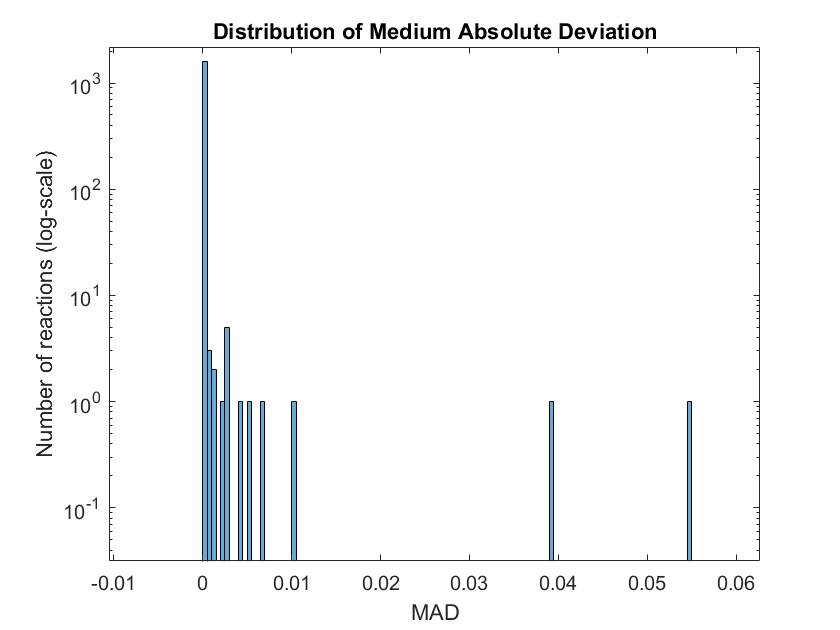

% Data distribution
figure;
histogram(mad_df(4, :));
set(gca, 'YScale', 'log');
title('Distribution of Medium Absolute Deviation');
xlabel("MAD");
ylabel("Number of reactions (log-scale)")

avg_df = avg_df';
heatmap(avg_df, ...
    "YDisplayLabels", "");